# Fourier Ring Correlation

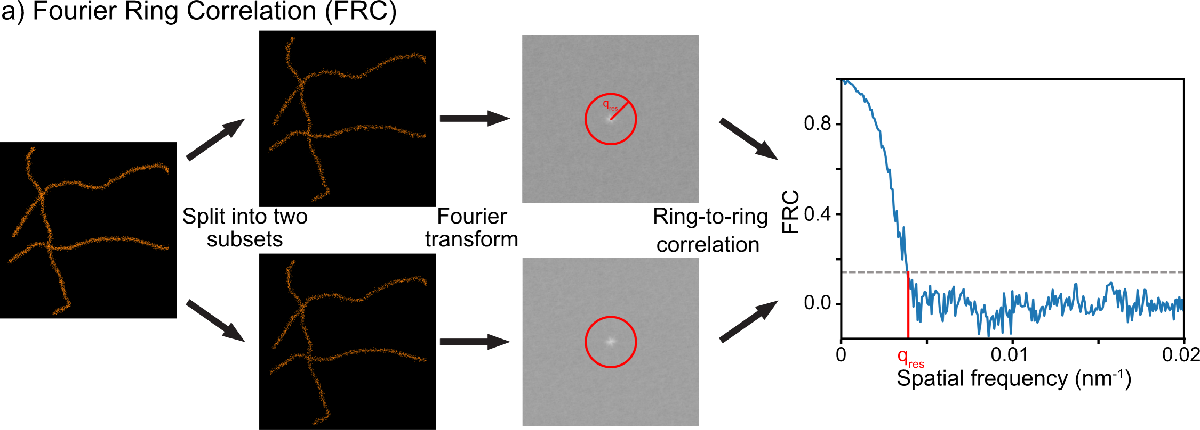

For FRC, we need to compare two images with each other, based on the same data.

Therefore, we briefly split the data randomly in 2, and create two images from these datasets, which are then correlated to each other at specific distances from the center of the image.

## Variable initiation

pixel_recon_dim = 20; % image reconstruction pixel size (nm), will be used for two-dimensional histograms, larger value -> faster computation (lower accuracy)

%We load the data
data = commonFunctions.readTXTRapidSTORM('Data\vimentin_BC2.txt');

% We find min/maximum X and Y values in our dataset. They will be required to determine the size of the reconstruction image.
min_x = floor(min(data(:,2)));
min_y = floor(min(data(:,3)));
max_x = ceil(max(data(:,2)));
max_y = ceil(max(data(:,3)));

%Localizations have to be randomly separated into two datasets.
coin = rand(size(data,1),1);
data1 = data(coin<0.5,:);
data2 = data(coin>=0.5,:);

## Creation of two images

For FRC to work, two images need to be correlated with each other. We create these two images from 1 dataset, for which we randomly assign every localization to belong to either dataset.

%We create images of these datapoints (also see Module 6)
image1 = hist3(data1(:,2:3),'Nbins',[ceil((max_x-min_x)/pixel_recon_dim), ceil((max_y-min_y)/pixel_recon_dim)]);
image2 = hist3(data2(:,2:3),'Nbins',[ceil((max_x-min_x)/pixel_recon_dim), ceil((max_y-min_y)/pixel_recon_dim)]);

%The images should be normalized for correlation, so that the total sum of
%the images is 1
image1 = image1./sum(sum(image1));
image2 = image2./sum(sum(image2));

## Fourier transform of images

The images need to be Fourier-transformed to allow for correlation calculations. We additionally compute a few maps based on these Fourier transformations.

%Fourier Transforms of the images are created
image1_f = fft2(image1);
image2_f = fft2(image2);

%Now we create three matrices that are needed to compute the FRC. They are
%based on the Fourier Transform images
%Note that these images need to be fft-shifted, as the zero-frequency
%component is expected to be in the center of the image.
af1f2 = fftshift(real(image1_f.*conj(image2_f)));
af1_2 = fftshift(abs(image1_f).^2);
af2_2 = fftshift(abs(image2_f).^2);

## Creation of distance map

Since FRC has to compute the correlation at different rings from the center of the images, we create a distance map. This is simply an image with values on how far every pixel is away from the center of the image (Euclidian distance).

Then, by looking at a specific distance value, we effectively can create a ring of that distance. This can be used as a mask for the Fourier-transform-based images created earlier.

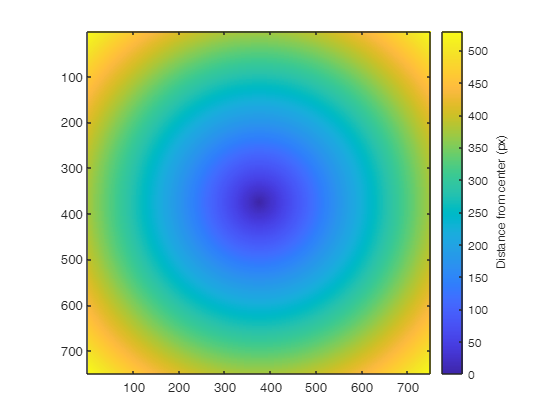

%Next, we create a distance map that simply contains the distances of every
%pixel to the center of the image. For this, we loop over all x and y positions
% to calculate the distance to the mid point
distancemap = zeros(size(image1));
midpoint = floor(size(image1)/2);
for xx = 1:size(image1,1)
    for yy = 1:size(image1,2)
        distancemap(xx,yy) = round(sqrt((xx-midpoint(1))^2+(yy-midpoint(2))^2));
    end
end

%We can show this distance map
figure()
imagesc(distancemap)
axis square
cbar = colorbar; cbar.Label.String = 'Distance from center (px)';

## Calculation of FRC plot

Now, we determine FRC values at different distances to the center.

%Now we calculate the total value that the af1f2, af1_2 and af2_2 images
%have at specific distances from the center of the image (i.e. at specific
%rings centered around the center of the image)

%First we assign a maximum distance (1-dimensional length of the image),
%and create a few empty matrices.
max_dist = floor(size(distancemap,1)/2);
f1f2_r = zeros(max_dist,1);
f12_r = zeros(max_dist,1);
f22_r = zeros(max_dist,1);
FRC_values = zeros(max_dist,1);

%Now we loop over all pixel distances, find which pixels in the distancemap have
%these distances (i.e. this creates circles in the map), and
%calculate the sum of these pixels in the af1f2, af1_2, and af2_2 images.
for d = 1:max_dist
    ringMap = (distancemap == d);
    f1f2_r(d) = sum(af1f2(ringMap));
    f12_r(d) = sum(af1_2(ringMap));
    f22_r(d) = sum(af2_2(ringMap));
    %Now the FRC values are calculated as follows
    FRC_values(d) = (f1f2_r(d)./sqrt(f12_r(d).*f22_r(d)));
end

## Resolution determination

Finally, we do some clean-up (e.g. sometimes a NaN (not-a-number) value is encountered, which are filtered out and replaced by a value calculated via interpolation of the neighbours), and we calculate the resolution by looking where the FRC plot crosses the value of 1/7.

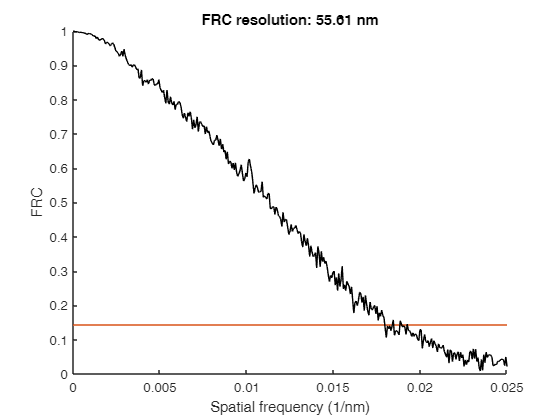

%We have to interpolate any NaNs with the interp1 function
x = 1:length(FRC_values) ;
FRC_values(isnan(FRC_values)) = ...
    interp1(x(~isnan(FRC_values)),FRC_values(~isnan(FRC_values)),x(isnan(FRC_values))) ;

%And we can plot the FRC
figure()
hold on
%The x-axis goes from 0 to 1/(2*pixel_recon_dim)
qmax = 1/(2*pixel_recon_dim);
linearRange = linspace(0,qmax, length(FRC_values));
%We plot a line and the FRC curve
plot(linearRange,ones(length(linearRange),1).*[1/7 1/7])
plot(linearRange,FRC_values,'k-')

%Lastly, we can find the intersection of this curve with the value 1/7
FRCresolutionID = find(FRC_values<1/7,1,'first');
%The actual resolution is the reprocicated value
FRCresolution = 1/linearRange(FRCresolutionID);
axis([0 inf 0 1])
xlabel('Spatial frequency (1/nm)')
ylabel('FRC')
title(['FRC resolution: ' num2str(round(FRCresolution,2)) ' nm'])